# **Program 1.1**

# **Generation of elementary signals in discrete time**

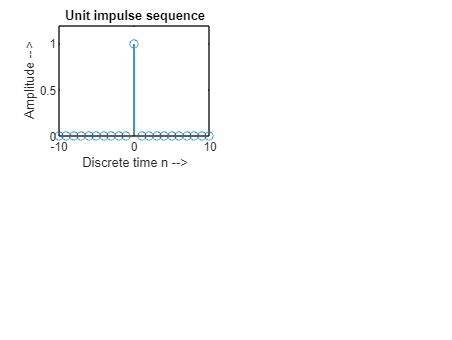

% Unit impulse sequence

n = -10:1:10 ;
impulse = [zeros(1,10), ones(1,1), zeros(1,10)] ;

subplot(2,2,1) ;
stem(n, impulse) ;
xlabel('Discrete time n -->');
ylabel('Amplitude -->');
title('Unit impulse sequence');
axis([-10 10 0 1.2]);

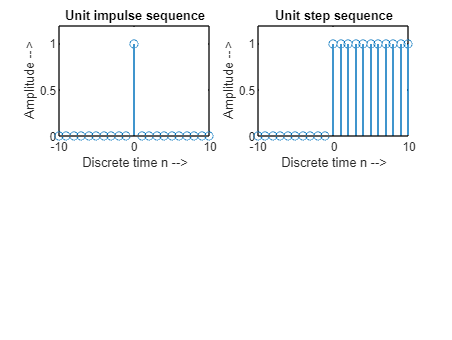

% Unit step sequence

n = -10:1:10 ;
step = [zeros(1,10), ones(1,11)] ;

subplot(2,2,2) ;
stem(n, step) ;
xlabel('Discrete time n -->');
ylabel('Amplitude -->');
title('Unit step sequence');
axis([-10 10 0 1.2]);

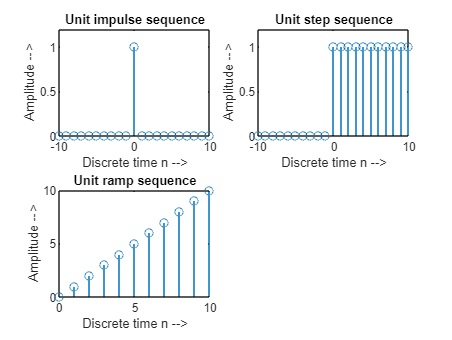

% Unit ramp sequence

n = 0:1:10 ;
ramp = n ;

subplot(2,2,3) ;
stem(n, ramp) ;
xlabel('Discrete time n -->');
ylabel('Amplitude -->');
title('Unit ramp sequence');

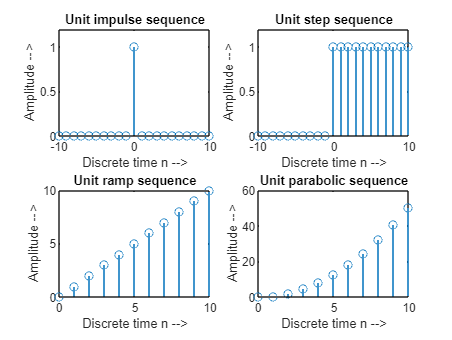

% Unit parabolic sequence

n = 0:1:10 ;
parabolic = 0.5*(n.^2) ;

subplot(2,2,4) ;
stem(n, parabolic) ;
xlabel('Discrete time n -->');
ylabel('Amplitude -->');
title('Unit parabolic sequence');

# **Program 1.2**

# **Generation of a discrete time exponential sequence**

**The signal is x(n) = a^n**

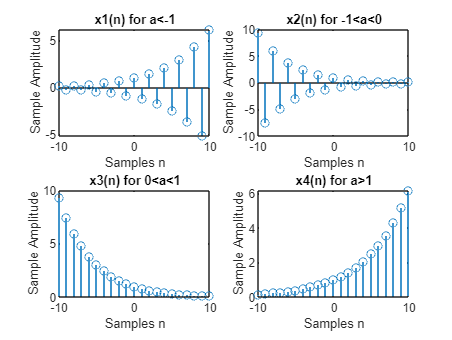

n = -10:1:10 ;

% for a<-1
a = -1.2 ;
x1 = a.^n ;
subplot(2,2,1) ;
stem(n, x1) ;
title('x1(n) for a<-1') ;
xlabel('Samples n') ;
ylabel('Sample Amplitude') ;

% for -1<a<0
a = -0.8 ;
x2 = a.^n ;
subplot(2,2,2) ;
stem(n, x2) ;
title('x2(n) for -1<a<0') ;
xlabel('Samples n') ;
ylabel('Sample Amplitude') ;

% for 0<a<1
a = 0.8 ;
x3 = a.^n ;
subplot(2,2,3) ;
stem(n, x3) ;
title('x3(n) for 0<a<1') ;
xlabel('Samples n') ;
ylabel('Sample Amplitude') ;

% for a>1
a = 1.2 ;
x4 = a.^n ;
subplot(2,2,4) ;
stem(n, x4) ;
title('x4(n) for a>1') ;
xlabel('Samples n') ;
ylabel('Sample Amplitude') ;

# **Program 1.3**

# **Multiplication of discrete-time signals**

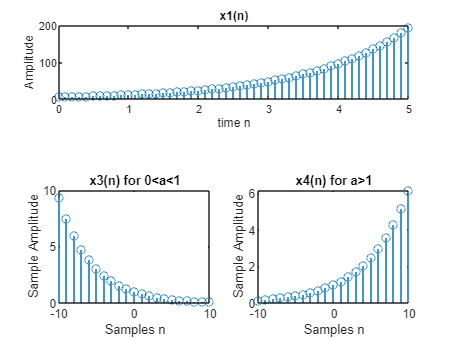

% Sequence1: x1(n) = 6*(a^n)

n = 0:0.1:5 ;
a = 2 ;
x1 = 6*(a.^n) ;
subplot(3,1,1) ;
stem(n, x1) ;
title('x1(n)') ;
xlabel('time n') ;
ylabel('Amplitude') ;

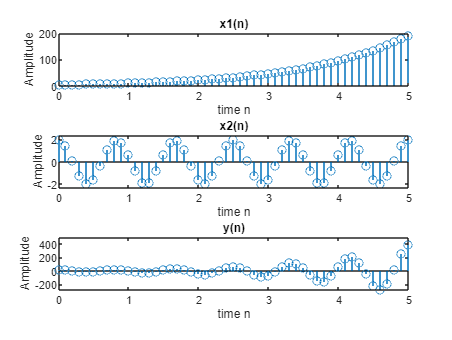


% Sequence2: x2(n) = 2*cos(wn)

f = 1.2 ;
x2 = 2*cos(2*pi*f*n) ;
subplot(3,1,2) ;
stem(n, x2) ;
title('x2(n)') ;
xlabel('time n') ;
ylabel('Amplitude') ;
axis([0 5 -2.4 2.4]);

% Multiplication of two sequences

y = x1.*x2 ;
subplot(3,1,3) ;
stem(n, y) ;
title('y(n)') ;
xlabel('time n') ;
ylabel('Amplitude') ;

# **Program 1.4**

# **Even and odd components of the sequence:**

**y(n) = u(n) - u(n-10)**

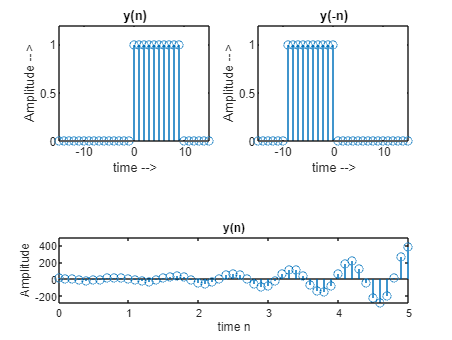

n = -15:1:15 ;

% Function y(n)
y1 = [zeros(1,15), ones(1,10), zeros(1,6)] ; 
subplot(2,2,1) ; 
stem(n,y1) ;
title('y(n)') ; 
xlabel('time -->') ;
ylabel('Amplitude -->') ;
axis([-15 15 0 1.2]) ; 

% Function y(-n)
y2 = fliplr(y1) ; 
subplot(2,2,2) ; 
stem(n,y2) ;
title('y(-n)') ; 
xlabel('time -->') ;
ylabel('Amplitude -->') ;
axis([-15 15 0 1.2]) ; 

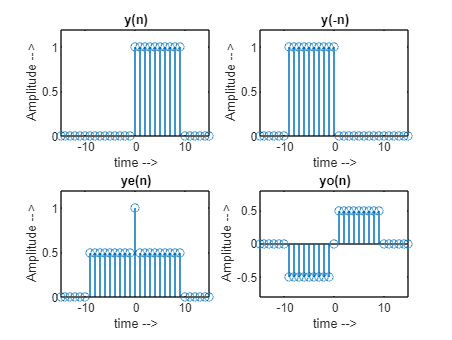


% Even Component of function y(n)
ye = 0.5*(y1 + y2) ; 
subplot(2,2,3) ; 
stem(n,ye) ;
title('ye(n)') ; 
xlabel('time -->') ;
ylabel('Amplitude -->') ;
axis([-15 15 0 1.2]) ; 

% Odd Component of function y(n)
yo = 0.5*(y1 - y2) ; 
subplot(2,2,4) ; 
stem(n,yo) ;
title('yo(n)') ; 
xlabel('time -->') ;
ylabel('Amplitude -->') ;
axis([-15 15 -0.8 0.8]) ; 

# **Program** 1.5

# Generation of the composite sequence:

### x(n) = u(n+3) + 5.u(n-15) + 4.u(n+10)

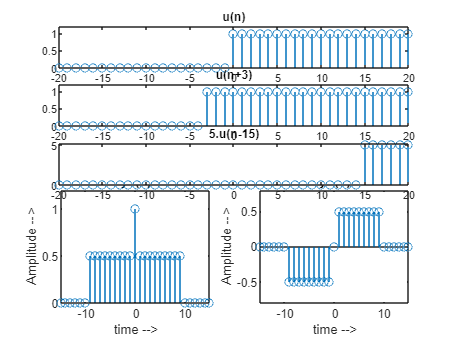

n = -20:1:20 ; 

% Function u(n)
u = [zeros(1,20), ones(1,21)] ; 
subplot(5,1,1)
stem(n,u) ; 
title('u(n)') ;
axis([-20 20 0 1.2]) ; 

% Function u1(n) = u(n+3)
u1 = [zeros(1,17), ones(1,24)] ; 
subplot(5,1,2)
stem(n,u1) ; 
title('u(n+3)') ;
axis([-20 20 0 1.2]) ;

% Function u2(n) = 5*u(n-15)
u2 = 5*[zeros(1,35), ones(1,6)] ; 
subplot(5,1,3)
stem(n,u2) ; 
title('5.u(n-15)') ;
axis([-20 20 0 5.2]) ;

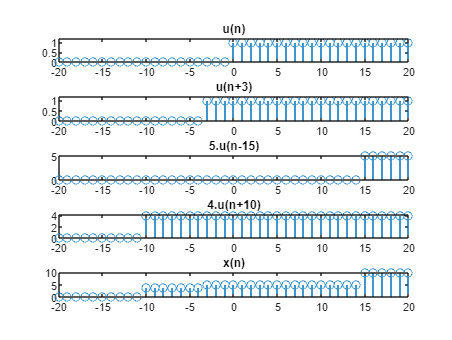


% Function u3(n) = 4*u(n+10)
u3 = 4*[zeros(1,10), ones(1,31)] ; 
subplot(5,1,4)
stem(n,u3) ; 
title('4.u(n+10)') ;
axis([-20 20 0 4.2]) ;

% Function x(n) = u(n+3) + 5.u(n-15) + 4.u(n+10)
x1 =u1 + u2 + u3 ; 
subplot(5,1,5)
stem(n,x1) ; 
title('x(n)') ;
axis([-20 20 0 10.2]) ;

# **Program** 1.6

# Generation of swept frequency sinusoidal signal

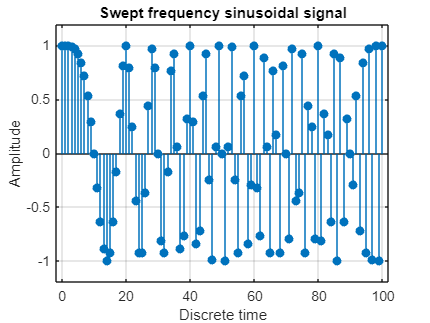

n = 0:100 ;
a = pi/2/100 ;
b = 0 ;
arg = a * n .* n + b * n ;
x = cos(arg) ;
stem(n,x,'filled') ;
xlabel('Discrete time') ;
ylabel('Amplitude') ;
title('Swept frequency sinusoidal signal') ;
grid on
axis([-2 102 -1.2 1.2]) ;

# **Program** 1.7

# Checking the time-invariance property

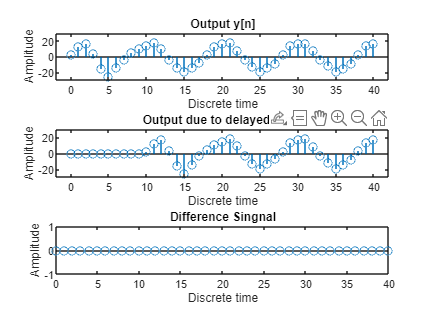

n = 0:40 ;
D= 10 ;
x = 3*cos(2*pi*0.1*n) - 2*cos(2*pi*0.4*n) ;
xd = [zeros(1,D) x] ;
num = [2.2403 2.4908 2.2403] ;
den = [1 -0.4 0.75] ;
ic = [0 0] ;
y = filter (num, den, x, ic) ;
yd = filter (num, den, xd, ic) ;
d = y - yd(1 + D:41 + D) ;

subplot(3,1,1) ;
stem(n,y) ;
xlabel('Discrete time') ;
ylabel('Amplitude') ;
title('Output y[n]') ;
axis([-2 42 -30 30]) ;


subplot(3,1,2) ;
stem(n, yd(1:41)) ;
xlabel('Discrete time') ;
ylabel('Amplitude') ;
title('Output due to delayed input') ;
axis([-2 42 -30 30]) ;

subplot(3,1,3) ;
stem(n,d) ;
xlabel('Discrete time') ;
ylabel('Amplitude') ;
title('Difference Singnal') ;

# **Program** 1.8

# Computation of Impulse Response

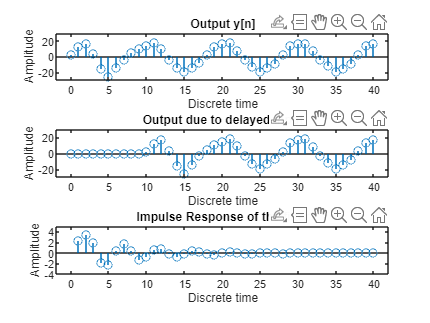


N = 40 ;
num = [2.2403 2.4908 2.2403] ;
den = [1 -0.4 0.75] ;
y = impz (num, den, N) ;
stem(y) ;
xlabel('Discrete time') ;
ylabel('Amplitude') ;
title('Impulse Response of the filter') ;
axis([-2 42 -4 5]) ;

# Program 1.9

# Checking the linearity of system

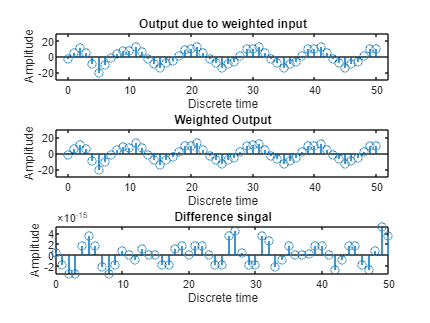

n = 0:50 ;
a = 2 ;
b = -3 ;
x1 = cos(2*pi*0.1*n) ;
x2 = cos(2*pi*0.4*n) ;
x = a*x1 + b*x2 ;
num = [2.2403 2.4908 2.2403] ;
den = [1 -0.4 0.75] ;
ic = [0 0] ;
y1 = filter (num, den, x1, ic) ;
y2 = filter (num, den, x2, ic) ;
y = filter (num, den, x, ic) ;
yt = a*y1 + b*y2 ;
d = y -yt ;

subplot(3,1,1) ;
stem(n,y) ;
xlabel('Discrete time') ;
ylabel('Amplitude') ;
title('Output due to weighted input') ;
axis([-2 52 -30 30]) ;

subplot(3,1,2) ;
stem(n,yt) ;
xlabel('Discrete time') ;
ylabel('Amplitude') ;
title('Weighted Output') ;
axis([-2 52 -30 30]) ;

subplot(3,1,3) ;
stem(n,d) ;
xlabel('Discrete time') ;
ylabel('Amplitude') ;
title('Difference singal') ;

# Program 1.10

# Testing the stability of a system

num = [1 -0.8] ;
den = [1 1.5 0.9] ;
N = 200 ;
h = impz (num, den, N+1) ;
parsum = 0 ;
for k =N+1
    parsum = parsum + abs(h(k)) ;
    if abs(h(k)) < 10^(-6)
        break
    end
end

stem(h) ;
xlabel('Discrete time') ;
ylabel('Amplitude') ;
disp('Value = ') ;

Value = 


disp(abs(h(k))) ;

   1.6761e-05



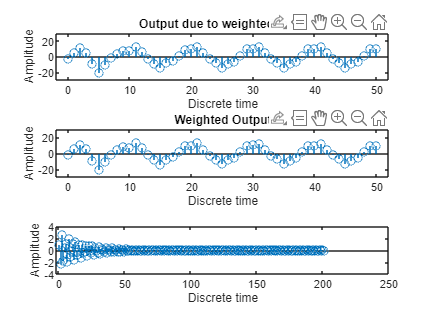

axis([-2 250 -4 4]) ;